data = 'C:/Users/andre/EE581-LandlideProj/data/archive/TrainData/';


img = data+"img/image_1.h5";
lbl = data+"mask/mask_1.h5";
img = h5read(img,"/img")

img = img(:,:,1) =

    1.1837    1.1837    1.1837    1.1890    1.1890    1.2205    1.2205    1.2214    1.2214    1.2214    1.2214    1.1846    1.1846    1.1846    1.1837    1.1837    1.1846    1.1819    1.1819    1.1765    1.1765    1.1765    1.1657    1.1657    1.1657    1.1621    1.1621    1.1621    1.1603    1.1603    1.1603    1.1612    1.1612    1.1612    1.1612    1.1630    1.1630    1.1630    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1774    1.1774    1.1846    1.1846    1.1846    1.1756    1.1756    1.1711    1.1711    1.1711    1.1396    1.1396    1.1396    1.1378    1.1378    1.1378    1.1180    1.1180    1.1180    1.1180    1.1180    1.1180    1.1180    1.1126    1.1126    1.1126    1.1126    1.1126    1.1135    1.1135    1.1135    1.1135    1.1126    1.1126    1.1126    1.1189    1.1189    1.1189    1.1198    1.1198    1.1315    1.1315    1.1315    1.1315    1.1315    1.1378    1.1378    1.1378    1.1378    1.1378    1.1378

img_slope = 1 - img(:,:,12);
size(img_slope)

ans =     14   128


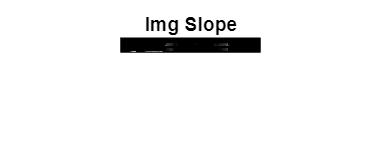

lbl = 1 - h5read(lbl,"/mask");
figure;
imshow(img_slope);
title("Img Slope");

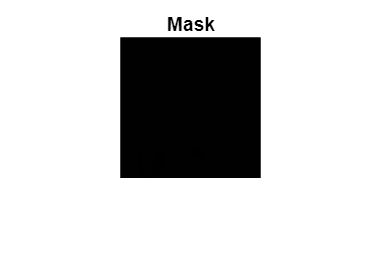

figure;
imshow(lbl);
title("Mask");

clc; clear; close all;

% Directory containing .h5 files
inputDir = 'C:\Users\andre\Year5\EE581\Project\archive\TrainData\img'; % Change this to your directory

% Get list of .h5 files
h5Files = dir(fullfile(inputDir, '*.h5'))

for i = 1%:length(h5Files)
    % Full path to the .h5 file
    h5FilePath = fullfile(inputDir, h5Files(i).name)
    
    % Read the HDF5 dataset (assuming dataset name is 'data', change if needed)
    info = h5info(h5FilePath)
    datasetName = info.Datasets(1).Name % Modify if necessary
    imgData = h5read(h5FilePath, ['/' datasetName])
    
    % Extract channels (assuming BGR ordering)
    B = imgData(:,:,1);
    size(B)
    G = imgData(:,:,2);
    R = imgData(:,:,3);
    
    % Combine into an RGB image
    rgbImage = cat(3, R, G, B);

    figure;
    imshow(rgbImage)
end
% 
% 
%     % Normalize if needed (convert to uint8 if data is not in 0-255 range)
%     if max(rgbImage(:)) > 1
%         rgbImage = uint8(rgbImage);
%     else
%         rgbImage = uint8(rgbImage * 255);
%     end
% 
%     % Save the image
%     [~, name, ~] = fileparts(h5Files(i).name);
%     outputFilePath = fullfile(outputDir, [name, '.png']);
%     imwrite(rgbImage, outputFilePath);
% 
%     fprintf('Saved: %s\n', outputFilePath);
% end
% 
% disp('Processing complete.');



clc; clear; close all;

% Directory containing .h5 files
inputDir = 'C:\Users\andre\Year5\EE581\Project\archive\TrainData\img'; % Change this to your directory
outputDir = 'path_to_output_directory'; % Change this to your desired output directory
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Get list of .h5 files
h5Files = dir(fullfile(inputDir, '*.h5'));

for i = 1:length(h5Files)
    % Full path to the .h5 file
    h5FilePath = fullfile(inputDir, h5Files(i).name);
    
    % Read the HDF5 dataset (assuming dataset name is 'data', change if needed)
    info = h5info(h5FilePath);
    datasetName = info.Datasets(1).Name; % Modify if necessary
    imgData = h5read(h5FilePath, ['/' datasetName]);
    
    % Extract channels (assuming BGR ordering)
    B = imgData(:,:,1);
    G = imgData(:,:,2);
    R = imgData(:,:,3);
    
    % Combine into an RGB image
    rgbImage = cat(3, R, G, B);
    
    % Normalize if needed (convert to uint8 if data is not in 0-255 range)
    if max(rgbImage(:)) > 1
        rgbImage = uint8(rgbImage);
    else
        rgbImage = uint8(rgbImage * 255);
    end
    
    % Save the image
    [~, name, ~] = fileparts(h5Files(i).name);
    outputFilePath = fullfile(outputDir, [name, '.png']);
    imwrite(rgbImage, outputFilePath);
    
    fprintf('Saved: %s\n', outputFilePath);
end

disp('Processing complete.');

